## Part D: Regression 

When doing any kind of regression analysis we need to consider what the relationship between the independent and dependent variables is expected to be. Too often, people produce a linear fit between two variables that do not follow a linear response. If the expected relationship is non-linear, then you should consider a non-linear function or transformation of the xData, yData, or both. Whilst this is often possible to achieve using a high order polynomial, interpretation of the coefficients may be more troublesome than transformation of the data. Let's work through some examples here:

First, lets try to find a solution for variables where the `yObs` values increase rapidly to small changes in `xObs` when `xObs` is small, and then the rate of change slows dramatically as the value of `xObs` increases. In this situation, a linear fit can be achieved by performing a `log10(x)`. This produces what is known as a linear-log model. Work through the script by using breakpoints and stepping each line to understand how the code is executed:

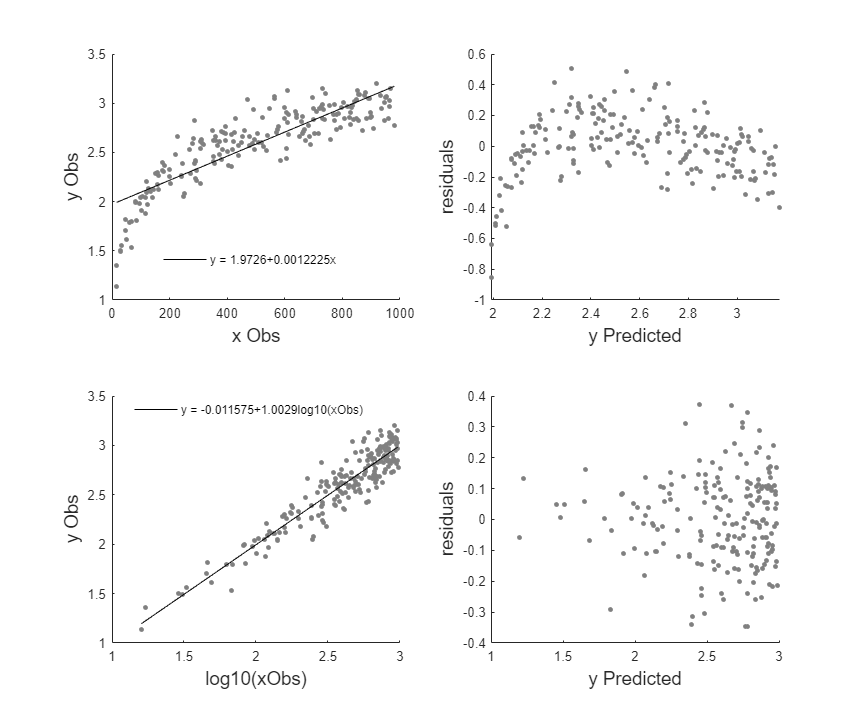

run('log10_transform_example.m');

Next we do the same with data where `yObs` increase rapidly to small changes in `xObs` when `xObs` is small, and then the rate of change slows slightly as the value of `xObs` increases. In this situation, a linear fit can be achieved by performing a `sqrt(x)`. Work through the script by using breakpoints and stepping each line to understand how the code is executed:

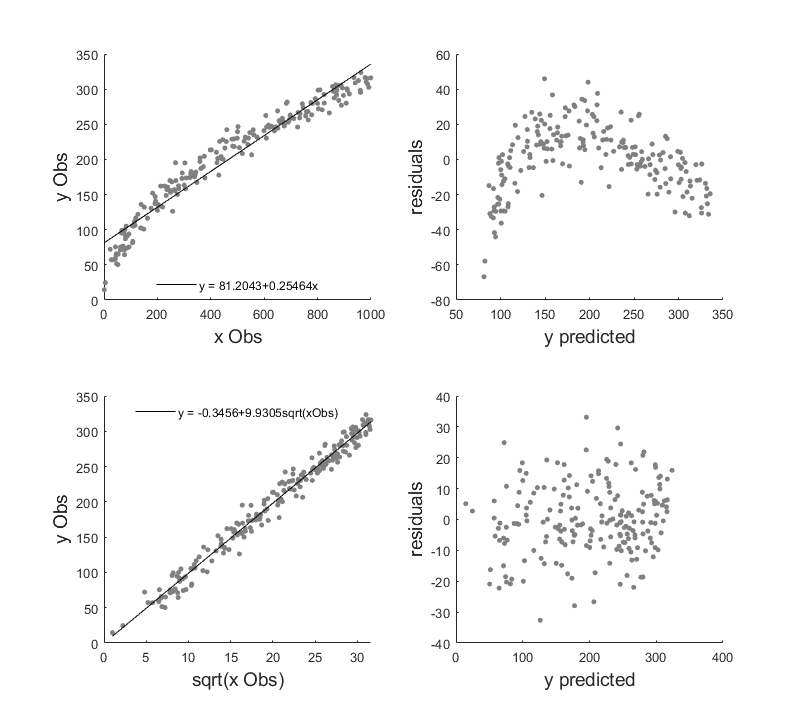

run('sqrt_transform_example.m');

Next we do the same with data where `yObs` increase slowly to changes in `xObs` when `xObs` is small, and then the rate of change increases as the value of `xObs` increases. In this situation, a linear fit can be achieved by performing a `log10` transformation on both the `xObs` and `yObs`. This is known as a power-law, or power model, and is extremely useful in the geosciences. Work through the script by using breakpoints and stepping each line to understand how the code is executed:

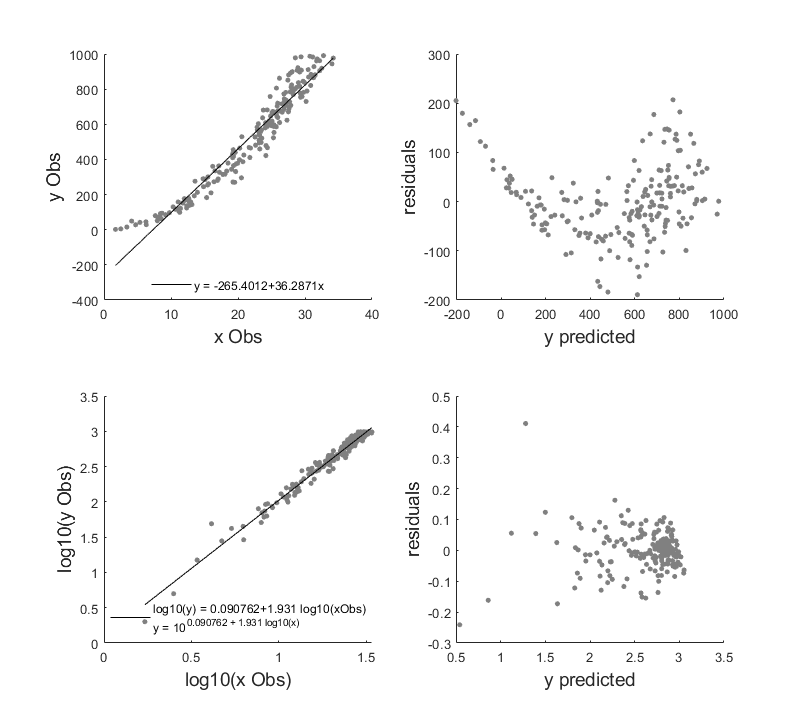

run('log10_log10_transform_example.m');

Finally, let's try it with some real data hosted on gitHub:

The following three commands reset the workspace by clearing all of the variables, closing all open Figures, and clearing the command line.

clear all; close all; clc;

Define the working folder where data for Block 04 is stored:

folderIn = 'C:\_git_local\GEO8026_22_23\Block 04\data\';

Read the data into MATLAB. Note that two seperate lists of characters can be joined into one through the use of square brackets:  

C = readtable([folderIn 'regress_example_data1.xlsx']); 

The data that we have just loaded is a` 325x2 `array consisting of independent data `(:,1)`, and response/dependant variable `(:,2)`. Let's extract this data into two seperate variables:

xIn = C{:,1}; % Extract the first column
yIn = C{:,2}; % Extract the second column

Let's perform an analysis on this data:

xIn = C{:,1}; % Extract the first column
yIn = C{:,2}; % Extract the second column

% Run a linear regression
[xData,yData]       = prepareCurveData(xIn,yIn);
t_out               = length(xData);
xData(1:t_out,2)    = 1; % Prep the data for regression
[b,~,r,~,stats]     = regress(yData,xData); % Run the regression
Original_r2         = stats(1,1); % Pull out the R2 value
Original_p          = stats(1,3); % Pull out the p value

%Let's plot the results:
f4 = figure(); hold on;
ax1_4     = subplot(2,2,1); hold on;
set(f4,'units','normalized','outerposition',[0 0 0.5 1]); 
h(1)      = scatter(xData(:,1),yData,... % we need to specify only the first column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);

intervals       = min(xData):0.01:max(xData);  % we need to specify the range of values to calculate the fit for.
h(2)            = plot(intervals,b(2) + b(1).*intervals,'k-'); % Plot the best-fit: b1 = slope, b2 = intecept

ylabel('y Obs','FontSize', 14);
xlabel('x Obs','FontSize',14);
h_leg(1) = legend(h(2), ['y = ' num2str(b(2)) '+' num2str(b(1)) 'x']);
legend boxoff ;
set(h_leg(1),'Location','best');

% Let's examine the residuals
% The residual vs. fit plot can be used to detect non-linearity and/or unequal variance.
fitted  = b(2) + b(1).*xData(:,1); % caluclate the fitted estimate for each xObs
ax2_4   = subplot(2,2,2); hold on
h(3)    = scatter(fitted,r,... % plot the fit vs residuals
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);
xlabel('y predicted','FontSize', 14);
ylabel('residuals','FontSize', 14);

What we can observe from the above is that when we run a linear regression on the `xData` and `yData`, a strong ($R^{2}$ = 0.83) and statistically significant (P < 0.01). This indicates there is a strong response in the `yData` from changes in `xData`. As the p value is close to zero we can reject the null hypothesis that $\beta_1 = 0$. However, we should investigate further and check the residuals to try and detect non-linearity and/or unequal variance. When we look at the residuals plot we can see that the variance in the residuals is not equal across the range. This is termed heteroskedasticity and can lead to the estimation of less precise model coefficients. A common cause of this is that we have selected an an inappropriate model e.g. additional terms are required to explain the variance. We should therefore consider whether linear regression on the raw variables is the best course of action? One option is that we transform one or more of the variables as we did with the randomly generated data earlier. We could choose to transform the `xData`, `yData`, or both. Commonly, we would start with the `xData`. In this instance, performing a log transform on the x-axis data works improved the model to an acceptable level:

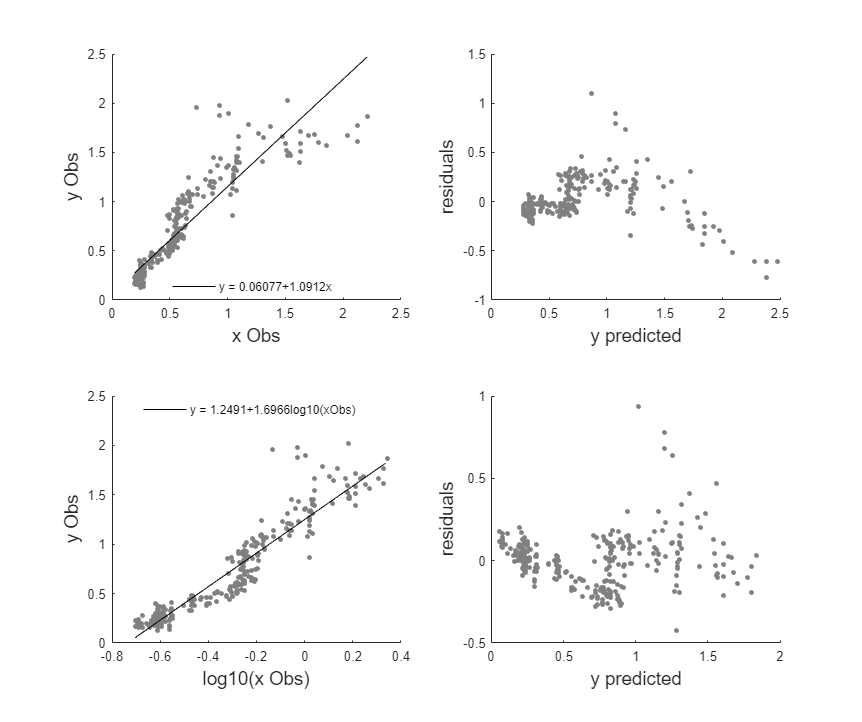

XData_mod               = log10(xData(:,1)); % here we transform the xObs by taking the log of x
t_out                   = length(XData_mod);
XData_mod(1:t_out,2)    = 1; % Prep the data for regression with a column of ones
[b,~,r,~,stats]         = regress(yData,XData_mod); % Run the regression and pull out the coefficients, residuals, stats
Original_r2             = stats(1,1); % Pull out the R2 value
Original_p              = stats(1,3); % Pull out the p value

%Let's plot the results:
ax3_4   = subplot(2,2,3); hold on
h(4)    = scatter(XData_mod(:,1),yData,... % we need to specify only the column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);

intervals   = min(XData_mod):0.01:max(XData_mod);  % we need to specify the range of values to calculate the fit for.
h(5)        = plot(intervals,b(2) + b(1).*intervals,'k-'); % Plot the best-fit: b1 = slope, b2 = intecept
ylabel('y Obs','FontSize', 14);
xlabel('log10(x Obs)','FontSize', 14);

h_leg(2) = legend(h(5), ['y = ' num2str(b(2)) '+' num2str(b(1)) 'log10(xObs)']);
legend boxoff ;
set(h_leg(2),'Location','best');

% Let's examine the residuals
% The residual vs. fit plot can be used to detect non-linearity and/or unequal variance.
fitted  = b(2) + b(1).*XData_mod(:,1); % caluclate the fitted estimate for each xObs
ax4_4   = subplot(2,2,4); hold on
h(6)    = scatter(fitted,r,... % plot the fit vs residuals
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10);
xlabel('y predicted','FontSize', 14);
ylabel('residuals','FontSize', 14);

We can now see that the variance has become more equal through the incorporation of this transformation (log of `xData`). Furthermore, the $R^{2}$ has increased from 0.83 to 0.89 indicating higher explained variance. Whilst we have applied linear regression to the technique, the resultant fit is now no longer linear due to the trasformation. Instead, this is a linear-log fit.

## Part E: Uncertainty 

Now that we have a model which is capable of describing the relationship between `xObs` and `yObs`, we need to consider the uncertainty associated with these estimates. Each coefficient will have uncertainty attached to it. If we assume that the errors are normally distributed, we can extract the uncertainty from the `regress` command (see variable `bint`). However, we can't always assume that our errors are normally disctibuted in which case these estimates of uncertainty may be inaccurate. In order to remove this bias, we can employ an approach known as `bootstrapping`. It effectively samples the data many times to obtain a better estimate of the regression coefficients. This can be acheived by resampling the cases (Approach 1), or resampling the residuals (Approach 2). Resampling the cases makes no assumption that the model that we have chosen is correct. It resamples the data `n` times and produces a new best fit for each random selection of measurements. Conversely, resampling the residuals assumes that the model that has been produced is correct. It then randomly samples the residuals from across the measurements, adds these to the prediction and computes a new best fit. Because resampling the residuals assumes that the developed model is correct, the `ci` associated with this tends to be smaller than when they are extracted using the resampling of the cases.

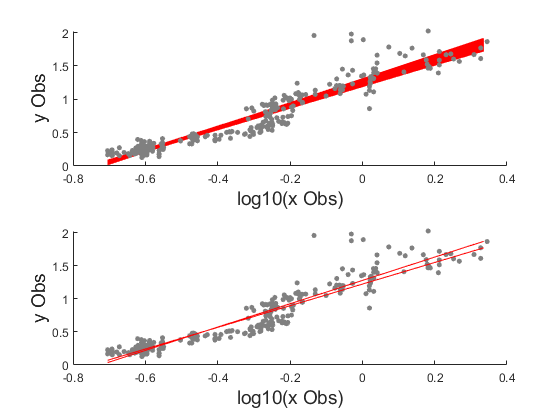

x           = XData_mod;
y           = yData;
intervals   = min(x):0.01:max(x);  % we need to specify the range of values to calculate the fit for.

% Approach 1: Resample the cases
p_boot             = bootstrp(2000,'polyfit',x(:,1),y,1); % Bootstrap the data 2000 times
p_boot_slope       = p_boot(50:1949,1); % Remove the upper and lower 2.5% of the slopes i.e. use 95%
p_boot_intercept   = p_boot(50:1949,2); % Remove the upper and lower 2.5% of the intercepts i.e. use 95%

% Plot the data
figure(); hold on;
ax5     = subplot(2,1,1); hold on
for a = 1:length(p_boot_slope)
    plot(intervals,p_boot_intercept(a,1) + p_boot_slope(a,1).*intervals,'r-'); hold on;
end

h(7)    = scatter(x(:,1),y,... % we need to specify only the column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10); hold on;

ylabel('y Obs','FontSize', 14);
xlabel('log10(x Obs)','FontSize', 14);

% Approach 2: Resample the model residuals
[b,bint,r,~,stats]  = regress(y,x);
yfit                = x*b; % predictions
resid               = y - yfit;

ci = bootci(2000,{@(bootr)regress(yfit+bootr,x),resid}, ...
    'Type','normal');

ax6     = subplot(2,1,2); hold on
h(7)    = scatter(XData_mod(:,1),yData,... % we need to specify only the column due to the column of ones
    'MarkerEdgeColor', [0.5,0.5,0.5],...
    'MarkerFaceColor', [0.5,0.5,0.5],...
    'SizeData', 10); hold on;

intervals   = min(XData_mod):0.01:max(XData_mod);  % we need to specify the range of values to calculate the fit for.
h(8)        = plot(intervals,ci(1,2) + ci(1,1).*intervals,'r-'); % Plot the best-fit: b1 = slope, b2 = intecept
h(9)        = plot(intervals,ci(2,2) + ci(2,1).*intervals,'r-'); % Plot the best-fit: b1 = slope, b2 = intecept

ylabel('y Obs','FontSize', 14);
xlabel('log10(x Obs)','FontSize', 14);

## Tasks for tomorrow's session:

- Explore your datasets, begining to produce functional relationships between variables.

- Consider extending the regression by using multiple regression where appropriate.